# Homework 3 [25 pt]

**Name**:

**Session** (ROB 599 or ROB 498): 

**Reading Assignment**: [https://www.matthewpeterkelly.com/index.html](https://www.matthewpeterkelly.com/index.html) 

**YouTube Playlist**: [https://www.youtube.com/playlist?list=PLEYKx4BGriISagN3Ihc-9L6Cw44vtzTD9](https://www.youtube.com/playlist?list=PLEYKx4BGriISagN3Ihc-9L6Cw44vtzTD9) 

**Submission**: Export this file as a **PDF** and submit it with **two videos** to Canvas. 

**Please **export** videos of quadrotor and pendulum motions by using the lower right button of animations to export.

*** Please submit files **separately** to Canvas instead of a zip file.

**Deadline**: 10/27/2025

- If you have any questions about the assignment or software, please use the Discussion function on Canvas to seek help!

- If your question was not addressed on Canvas, then reach out to GSI: Yulun Zhuang

- The live script for homework is still evolving, please check Canvas periodically to make sure you are working on the latest version

# Written Assignment

## Use LaTex for homework

Use LaTex syntax to anwer the written part of the assignment

Latex expressions can be brought up by pressing ctrl + shift + L in Windows or cmd + shift + L in Mac 

## Problem 1: Template for Locomotion [3 pt]

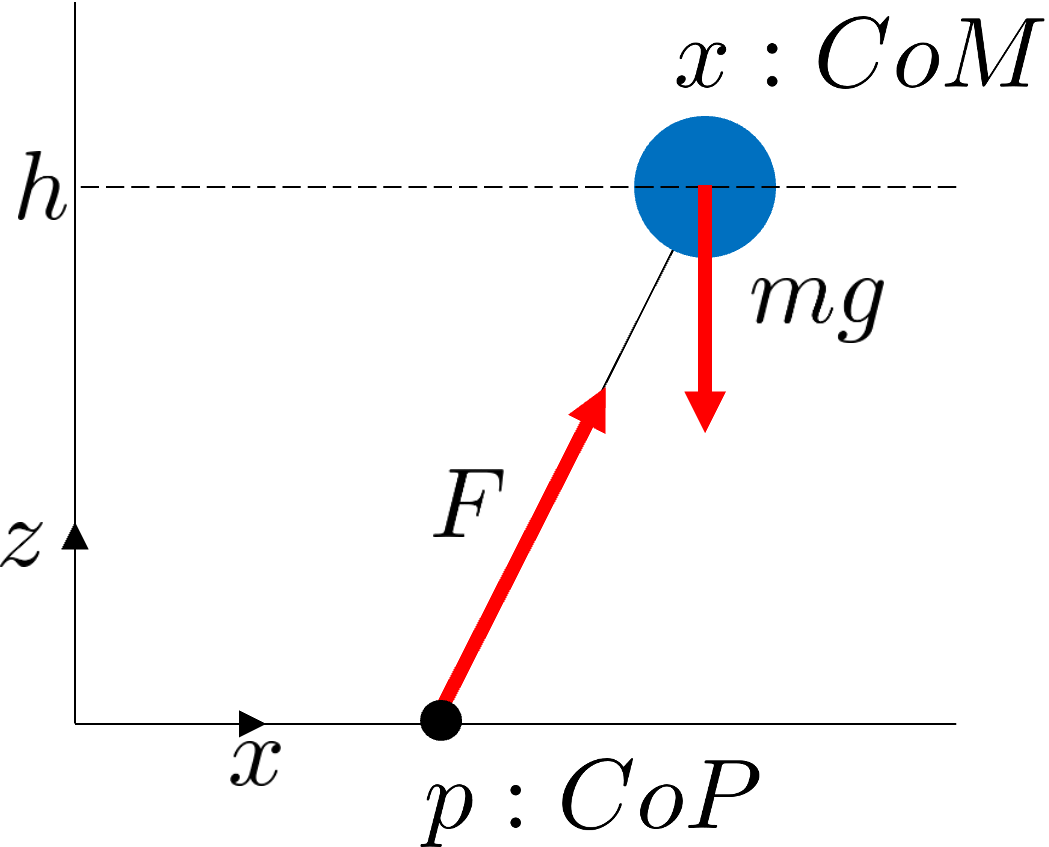

a) [1 pt] What is the LIP dynamics expressed using the notation defined in the above figure?


$$
\[
\ddot{x} = \omega^2 (x - p), \qquad \omega = \sqrt{\frac{g}{h}} .
\]$$


b) [1 pt] What is the analytical solution to the differential equation a), given initial condition $x(0)=x_0, \dot{x}(0) = \dot{x}_0$?

Hint: the solution involves hyperbolic sine and cosine.


$$\[
\ddot{x} - \omega^2 (x - p) = 0
\]
has the analytical solution:
\[
x(t) = p + (x_0 - p)\cosh(\omega t) + \frac{\dot{x}_0}{\omega}\sinh(\omega t),
\]
\[
\dot{x}(t) = \omega (x_0 - p)\sinh(\omega t) + \dot{x}_0 \cosh(\omega t).
\]$$


c) [1 pt] The **capture point** $\xi$ is the foot location such that, if you place the foot there *now* and keep it there, the robot will come to rest (i.e. $\dot{x}\rightarrow0$). Can you derive the expression for capture point?


$$\[
x(t) - \xi = (x(0) - \xi)e^{-\omega t}, \qquad 
\dot{x}(t) = \omega(\xi - x(t)) \to 0 \text{ as } t \to \infty.
\]
Thus the system comes to rest, and the expression for the capture point is:
\[
{\xi = x + \frac{\dot{x}}{\omega}}.
\]$$


## Problem 2: LQR [3 pt]

a) [1 pt] What is the HJB equation? Define each term in the recursive expression.


$$

\[
-\frac{\partial V}{\partial t}(x,t) = \min_{u} \left\{ l(x,u,t) + \nabla_x V(x,t)^\top f(x,u,t) \right\}, 
\quad V(x,T) = \phi(x).
\]
$$


b) [1 pt] What is the HJB equation for LQR problem?


$$\[
0 = \min_{u} \Big\{ x^\top Q x + u^\top R u + \nabla_x V(x)^\top (A x + B u) \Big\}.
\]$$


c) [1 pt] Derive the LQR linear feedback gain $K_{lqr}$ from the HJB equation in b).


$$\[
\frac{\partial}{\partial u}\{\cdots\} = 2 R u + 2 B^\top P x = 0 
\quad \Rightarrow \quad u^\star = -R^{-1} B^\top P x.
\]

\[
A^\top P + P A - P B R^{-1} B^\top P + Q = 0.
\]
Thus, the LQR linear feedback gain is:
\[
{K_{\mathrm{LQR}} = R^{-1} B^\top P}, \qquad 
u^\star(t) = -K_{\mathrm{LQR}} \, x(t).
\]$$


## Problem 3: Optimization [3 pt]

a) [1 pt] Newton's method: what is the Taylor expainsion that leads to the update rule? Can you write down the update rule?


$$
\[
\nabla^2 f(x_k)\,\Delta_k \;=\; -\,\nabla f(x_k),\qquad
\Delta_k \;=\; -\,\nabla^2 f(x_k)^{-1}\nabla f(x_k),
\]
and the update rule:
\[
{~x_{k+1}=x_k-\alpha_k\,\nabla^2 f(x_k)^{-1}\nabla f(x_k)~}.
\]$$


b) [1 pt] What are the KKT conditions for LP?


$$

\textbf{Primal feasibility}  \ \textbf{Dual feasibility} \ \textbf{Stationarity} \ \textbf{Complementary slackness} 

$$


c) [1 pt] To encode inequality constraint $1\leq x^2 \leq 2$ (donut) as part of the cost using log barrier function, can you write the penalty terms associated with the constraints?


$$
\[
g_1(x)=1-\|x\|^2\le0,\qquad g_2(x)=\|x\|^2-2\le0.
\]
The logarithmic barrier term (penalty added to the objective) is
\[
\{~\Phi_\mu(x) \;=\; -\,\mu\Big[\log(\|x\|^2-1)\;+\;\log(2-\|x\|^2)\Big]~,}
\]
valid for $1<\|x\|^2<2$.$$


## Problem 4: Quadrotor Dynamics [3 pt]

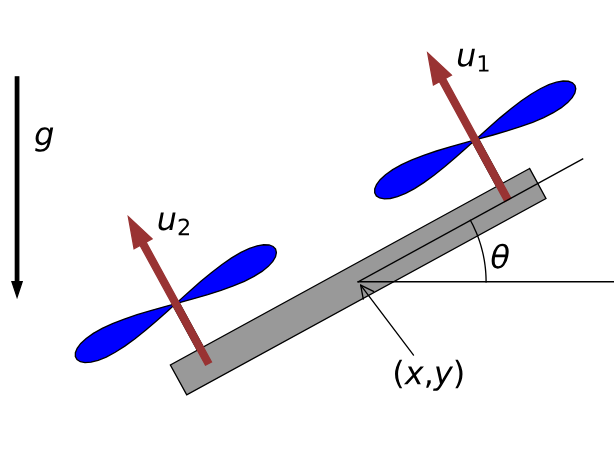

Reference: [https://underactuated.csail.mit.edu/acrobot.html#section3](https://underactuated.csail.mit.edu/acrobot.html#section3) 

a) [1 pt] Read through the reference. Define the state space and input vector. Write down the quadrotor dynamics.


$$
\dot{x} = \dot{x}, \ \dot{y} = \dot{y}, \dot{\theta} = \omega,  \ddot{x} = -\frac{1}{m}(u_1 + u_2)\sin\theta, \ddot{y} = \frac{1}{m}(u_1 + u_2)\cos\theta - g, 
\dot{\omega} = \frac{l}{I}(u_1 - u_2)
\end{aligned}
\]$$


b) [1 pt] Derive the continuously time linear dynamics around the nominal pose where $\theta=0$. Specifically, provide the expressions of the continuous time Jacobian matrices $A_c = \frac{\partial f}{\partial x}$ and $B_c = \frac{\partial f}{\partial u}$.


$$A_c =
\pmatrix{
0 & 0 & 0 & 1 & 0 & 0 \cr
0 & 0 & 0 & 0 & 1 & 0 \cr
0 & 0 & 0 & 0 & 0 & 1 \cr
0 & 0 & -g & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 0
}, \quad
B_c =
\pmatrix{
0 & 0 \cr
0 & 0 \cr
0 & 0 \cr
0 & 0 \cr
1/m & 1/m \cr
l/I & -l/I
}.
\]$$


c) [1 pt] Based on the continuous time linear dynamics, what is the discrete-time linear dynamics. Specifically, what are the Jacobian matrices $A_d, B_d$, assuming forward Euler integration with time step $dt$?


$$\[
A_d =
\pmatrix{
1 & 0 & 0 & dt & 0 & 0 \cr
0 & 1 & 0 & 0 & dt & 0 \cr
0 & 0 & 1 & 0 & 0 & dt \cr
0 & 0 & -gdt & 1 & 0 & 0 \cr
0 & 0 & 0 & 0 & 1 & 0 \cr
0 & 0 & 0 & 0 & 0 & 1
}, \quad
B_d =
\pmatrix{
0 & 0 \cr
0 & 0 \cr
0 & 0 \cr
0 & 0 \cr
dt/m & dt/m \cr
dt\,l/I & -dt\,l/I
}.
\]
$$


# Coding Assignment

## Codebase Structure & Setup

Execute the `setup.m` script **separately** to add paths of `spatical_v2` and check installation status of CasADi.

% clear; close all force;
% run ../../setup.m

## Assignment 1: LQR Control [4 pts]

% parameters
p.g = 9.81;
p.mass = 1;
p.inertia = 1e-2;
p.halfWidth = 0.2;

tDuration = 1;
dt = 0.01;
tstart = 0;
tend = dt;
MAXITER = floor(tDuration/dt);

% state X = [x, z, th, dx, dz, dth]
% control U = [u1, u2]
X0 = [0.2 0.8 0.5 -2 0 0]';
XDes = [0 1 0 0 0 0]';
Uff = 0.5 * p.mass * p.g * [1; 1];      % feedforward propeller forces
U = Uff;

t_ = 0;
X_ = X0(:)';
U_ = U(:)';

% linearize dynamics around the desired state and control
[Ac, Bc, dc] = getJacobian(XDes, Uff, p);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS
% - discretize dynamics using forward Euler integration
A = eye(6) + Ac * dt;
B = Bc * dt;
d = dc * dt;
% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% weighting matrices for discrete time LQR controller 
Q = diag([1, 1, 0.1, 0.01, 0.01, 0.01]);
R = 1e-3 * diag([1, 1]);


#### Function to be implemented

function [dXdt, U] = quad_dynamics(t,X,U,p)

[x, z, th] = deal(X(1), X(2), X(3));
[dx, dz, dth] = deal(X(4), X(5), X(6));
[u1, u2] = deal(U(1), U(2));

mass = p.mass;
halfWidth = p.halfWidth;
g = p.g;
inertia = p.inertia;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS
ddx = -(u1 + u2)/mass * sin(th);
ddz = (u1 + u2)/mass * cos(th) - g;
ddth = halfWidth/inertia * (u1 - u2);
% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dXdt = [dx; dz; dth; ddx; ddz; ddth];

end

function [Ac, Bc, dc] = getJacobian(X, U, p)
[x, z, th] = deal(X(1), X(2), X(3));
[u1, u2] = deal(U(1), U(2));

mass = p.mass;
halfWidth = p.halfWidth;
g = p.g;
inertia = p.inertia;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS
Ac = zeros(6);
Ac(1:3, 4:6) = eye(3);
Ac(4,3) = -(u1 + u2)/mass * cos(th);
Ac(5,3) = -(u1 + u2)/mass * sin(th);

Bc = zeros(6,2);
Bc(4,:) = -(1/mass) * sin(th);
Bc(5,:) = (1/mass) * cos(th);
Bc(6,:) = [halfWidth/inertia, -halfWidth/inertia];
% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dc = [0 0 0 0 -p.g 0]';

end

**Main Control Loop**

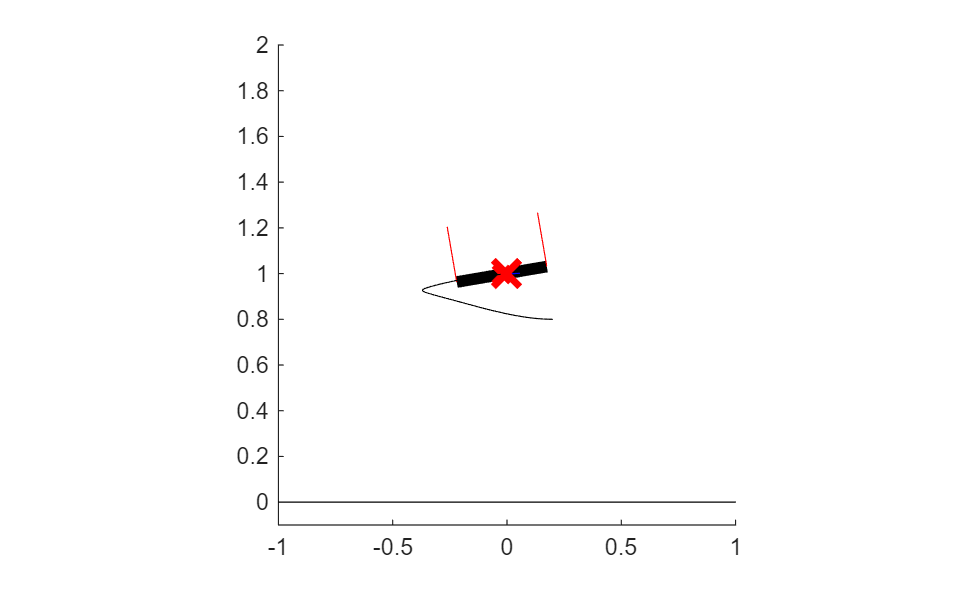

% Simulation Loop
for ii = 1:MAXITER
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % YOUR CODE STARTS
    % discrete-time LQR controller
    [K, ~, ~] = dlqr(A, B, Q, R); 
    U = Uff - K * (X0 - XDes);
    % YOUR CODE ENDS
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % integrator
    [t,X] = ode45(@(t,X)quad_dynamics(t, X, U, p), [tstart, tend], X0);
    
    % update
    tstart = tend;
    tend = tstart + dt;
    X0 = X(end,:)';
    
    % logging
    t_ = [t_; tstart];
    X_ = [X_; X0'];
    U_ = [U_; U'];
end

% animation
animate_quadrotor(t_, X_, U_, XDes, p)

## I used my own implementation of `animate_quadrotor.m`

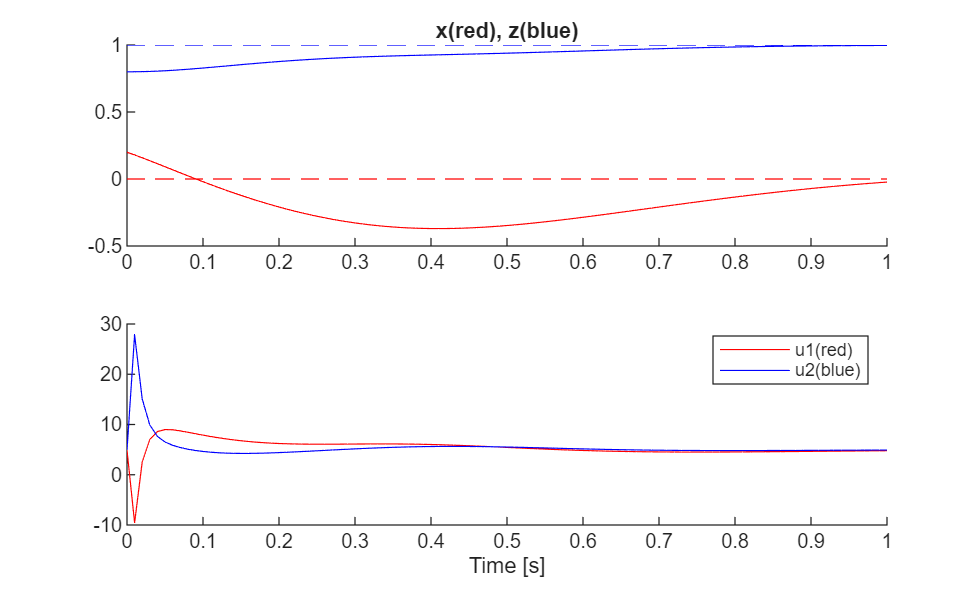

% Figures
clf
subplot(2,1,1)
hold on;
plot(t_, X_(:,1),'r')
plot(t_, X_(:,2),'b')
plot([t_(1),t_(end)], XDes(1)*[1 1],'r--')
plot([t_(1),t_(end)], XDes(2)*[1 1],'b--')
xlim([t_(1),t_(end)])
title('x(red), z(blue)')

subplot(2,1,2)
hold on
plot(t_, U_(:,1),'r')
plot(t_, U_(:,2),'b')
xlim([t_(1),t_(end)])
xlabel('Time [s]')
legend('u1(red)', 'u2(blue)')

## Assignment 2: Constrained Optimization [4 pt]

a) [2 pt] Newton's method with equality constraints

initialize_optimization()
maxRange = 1;
N = 100;

ans = function_handle with value:
    @fcn_f_grad_Hess


x = linspace(-2*maxRange,maxRange, N);
y = linspace(-maxRange,maxRange, N);
[X,Y] = meshgrid(x,y);
f = fcn_f_grad_Hess(X,Y);

x0 = [-1.2; 0.8];
lr = 0.17;
iter = 20;

figure; hold on
contour(X, Y, f, 90);
xlabel('x1','FontSize',16)
ylabel('x2','FontSize',16)
% Newton's method with equality constraints
A = [2,1];
b = -2;
path = newton_equality(x0, iter, A, b);

plot(path(1,:),path(2,:),'k-','Marker','o')
title('Newtons Method with Equality','FontSize',16)
for ii = 1:4
    xtext = ['x(',num2str(ii-1),')'];
    text(path(1,ii)+0.05,path(2,ii),xtext);
end

x1 = linspace(-2,1,51);
x2 = (b - A(1) * x1) / A(2);
plot(x1, x2, 'r-')
ylim([-1 1])

#### Function to be implemented

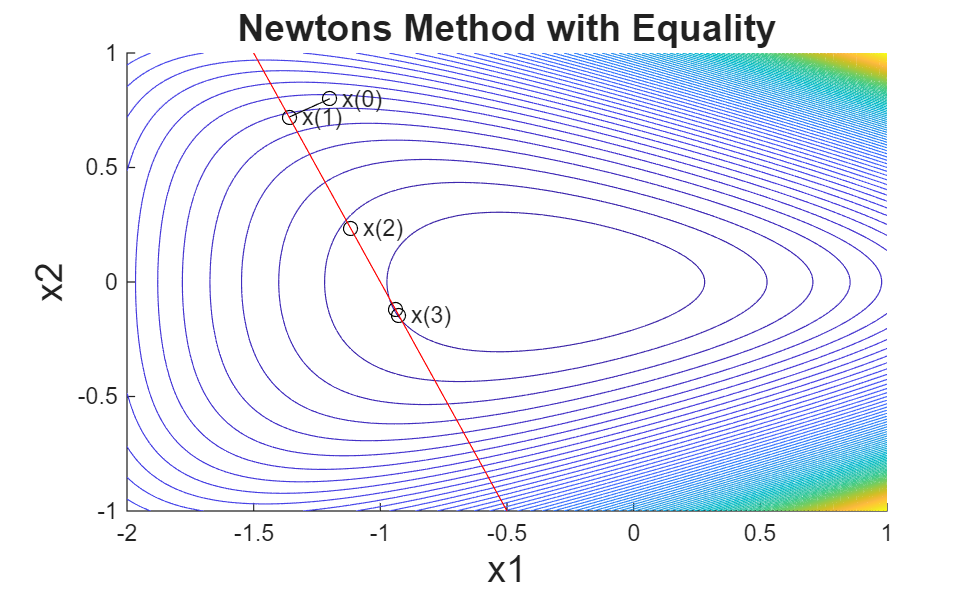

% Newton's method with equality constraints

function path = newton_equality(x0, iter, A, b)
path = x0;

% project x0 to the feasibility manifold
lam = -(A * x0 - b)/(A * A');
x0 = x0 + lam * A';
path = [path, x0];

for ii = 1:iter
    [~, grad, Hess] = fcn_f_grad_Hess(x0(1), x0(2));

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % YOUR CODE STARTS
    Amat = [Hess, A'; 
            A,   0];
    bvec = -[grad; A*x0 - b];

    dx_v = Amat \ bvec; 
    dx = dx_v(1:2);

    x0 = x0 + dx;
    % YOUR CODE ENDS
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    path = [path, x0(:)];
end

end

b) [2 pt] Newton's method with inequality constraints as barrier penalty

init_inequality()
figure; hold on
contour(X, Y, f, 90);

ans = function_handle with value:
    @fcn_ineq_grad_Hess


xlabel('x1','FontSize',16)
ylabel('x2','FontSize',16)

x0 = [0; 0.8];
path = newton_inequality(x0, iter);

plot(path(1,:),path(2,:),'k-','Marker','o')
title('Newtons Method with Equality','FontSize',16)
for ii = 1:4
    xtext = ['x(',num2str(ii-1),')'];
    text(path(1,ii)+0.05,path(2,ii),xtext);
end

x1 = linspace(-2,1,51);
x2 = 0.5 * x1.^2 + 0.1;
plot(x1, x2, 'r-')
ylim([-1 1])

#### Function to be implemented

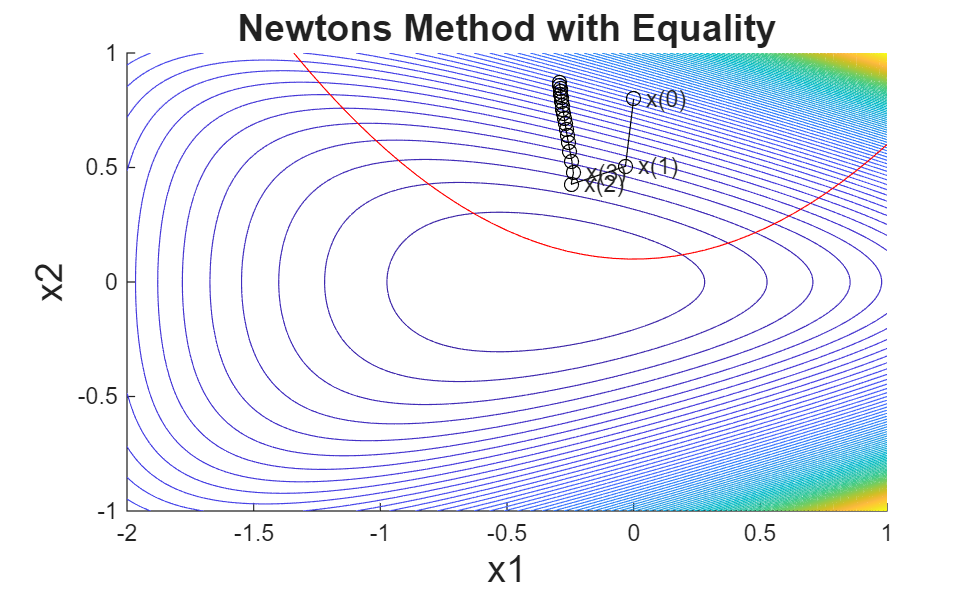

function init_inequality()

    syms x1 x2 t real
    x = [x1;x2];

    fi = - x2 + 0.5 * x1^2 + 0.1;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % YOUR CODE STARTS
    logBarrier = -t * log(-fi);
    grad_ineq = gradient(logBarrier, x);
    Hess_ineq = hessian(logBarrier, x);
    % YOUR CODE ENDS
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    input = {x, t};
    matlabFunction(fi,grad_ineq,Hess_ineq,"File","fcn_ineq_grad_Hess","Vars",input)
end

function path = newton_inequality(x0, iter)
    path = x0;
    for ii = 1:iter
        [~, grad, Hess] = fcn_f_grad_Hess(x0(1), x0(2));

        [~, grad_barrier, Hess_barrier] = fcn_ineq_grad_Hess(x0,ii);

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % YOUR CODE STARTS
        g = grad + grad_barrier;
        H = Hess + Hess_barrier; 

        x0 = x0 + (-H \ g);
        % YOUR CODE ENDS
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        path = [path, x0(:)];
    end
end

## Assignment 3: Multiple Shooting [5 pt]

Multiple shooting for simple pendulum

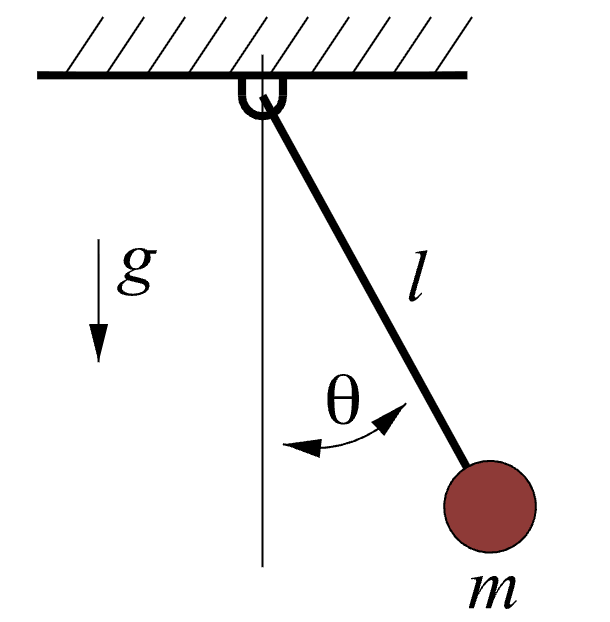

% run ../../setup.m
% parameters
p.Nms = 20;
p.Nseg = 5;
p.L = 0.5;
p.mass = 1;
p.g = 9.81;
p.nco = 4;
tauMax = 3;

% boundary states
s0 = 0;                     % the integrator for cost
X0 = [0; 0; s0];
Xf = [pi; 0];

% setup optimization
opti = casadi.Opti();       % optimization problem

co_tau = opti.variable(1, p.nco);
tf = opti.variable(1, 1);
Xms = opti.variable(3, p.Nseg);
opt_var = [co_tau, tf, Xms(:)'];

% simulate forward
ds = 1/(p.Nseg*p.Nms);
for jj = 1:p.Nseg
    if jj == 1
        X = X0;
    else
        X = Xms(:,jj-1);
    end

    for kk = 1:p.Nms
        s = ds * (p.Nms * (jj-1) + (kk-1));
        X = sim_forward(X, s, ds, opt_var, p);
        tau = polyval(opt_var(1:p.nco)', s);
        opti.subject_to(-tauMax <= tau <= tauMax);
    end
    opti.subject_to(X == Xms(:,jj));
end

opti.subject_to(Xms(1:2,end) == Xf(1:2));     % terminal state
opti.subject_to(tf >= 0.5);

obj = Xms(3,end) + 1 * tf^2;
opti.minimize(obj);

opti.set_initial(tf, 1);

opti.solver('ipopt');
sol = opti.solve();
% solution
co_tau_val = sol.value(co_tau)
tf_val = sol.value(tf)

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:      112
Number of nonzeros in inequality constraint Jacobian.:      398
Number of nonzeros in Lagrangian Hessian.............:       67

Total number of variables............................:       20
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:       17
Total number of inequality constraints...............:      101
        inequality constraints with only lower bounds:        1
   inequality constraints with lower and upper bounds:      100
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  1.0000000e+00 3.14e+00 5.00e-01  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

#### Function to be implemented

function [dXdt, tau] = dynamics(s, X, opt_var, p)

co_tau_val =   -43.0558   43.9169   -1.2874   -2.9915


    L = p.L;

tf_val = 2.0615

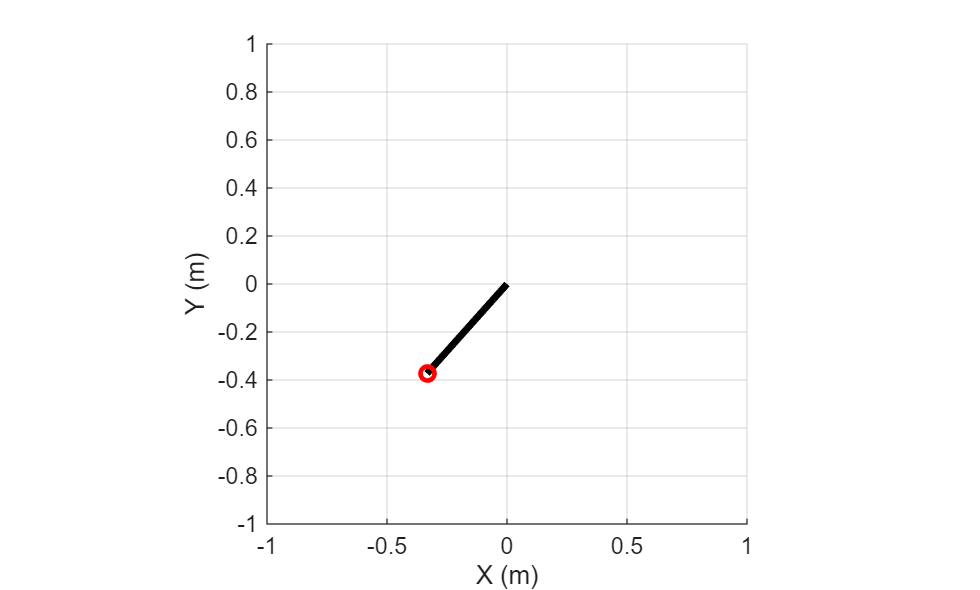

    mass = p.mass;
    g = p.g;
    nco = p.nco;

    q = X(1);
    tf = opt_var(nco+1);
    tau = polyval(opt_var(1:nco)', s);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % YOUR CODE STARTS
    ddq = (tau - mass * g * L * sin(q)) / (mass * L^2);
    ds = 0.5 * tau^2;  % integrator for the cost
    dq = X(2);
    dXdt = tf * [dq;
                 ddq;
                 ds];
    % YOUR CODE ENDS
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

end

% Animation
opt_sol = [co_tau_val, tf_val]; 
[Xout, tauout] = animate_pendulum(X0, opt_sol, p.Nms*p.Nseg, p);
tout = tf_val * linspace(0,1,p.Nms*p.Nseg);
make_figures(tout, Xout, tauout)

**I used my own implementation of **`animate_pendulum.m`

## Helper Functions

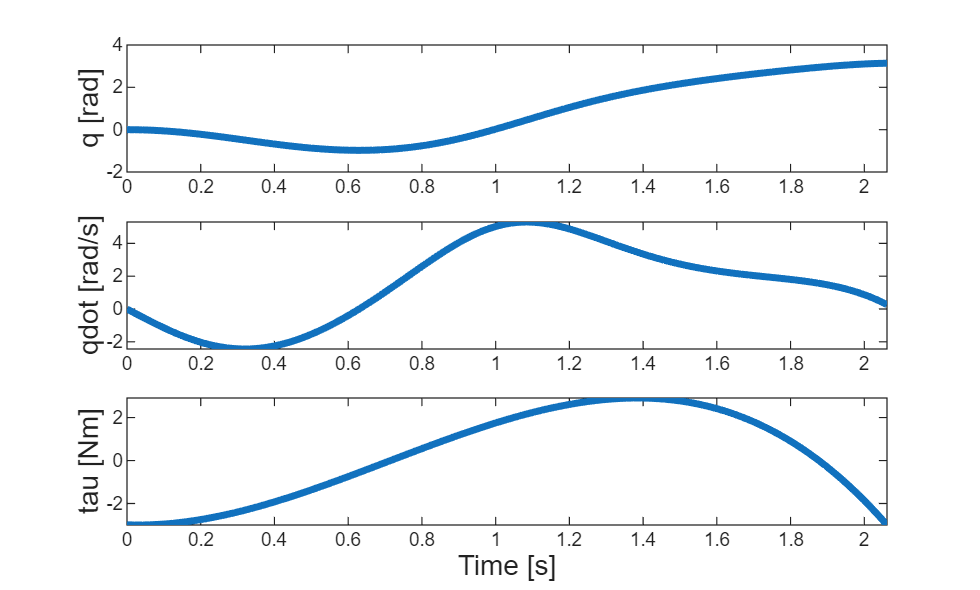

% LQR control for quadrotor

function animate_quadrotor(t_, X_, U_, XDes, p)
nt = length(t_);
for ii = 1:nt
    clf
    hold on;
    axis equal;
    xlim([-1, 1])
    ylim([-0.1, 2]);

    plotQuadrotor(X_(ii,:), U_(ii,:), p)
    % CoM trajectory
    plot(X_(1:ii,1), X_(1:ii,2), 'k')
    % Desired CoM
    plot(XDes(1),XDes(2),'rx','MarkerSize',16, 'LineWidth',3)

    pause(0.01);
end
end

function plotQuadrotor(X, U, p)
r = p.halfWidth;
[x, z, th] = deal(X(1), X(2), X(3));
[u1, u2] = deal(U(1), U(2));

% rotor body
p1 = [x;z] + rot(th) * [r; 0];
p2 = [x;z] + rot(th) * [-r; 0];
chain_rotor = [p1, p2];

% propelling force
scale = 0.05;
p1u = p1 + rot(th) * [0; u1] * scale;
p2u = p2 + rot(th) * [0; u2] * scale;
chain_u1 = [p1, p1u];
chain_u2 = [p2, p2u];

% CoM velocity
pcom  = X(1:2)';
vel = X(4:5)';
chain_vel = [pcom, pcom+vel*0.2];

hold on;
plot(chain_rotor(1,:), chain_rotor(2,:),'k','linewidth',5)
plot(chain_u1(1,:), chain_u1(2,:), 'r');
plot(chain_u2(1,:), chain_u2(2,:), 'r');
plot(chain_vel(1,:), chain_vel(2,:), 'b');
plot(x, z, 'rx','linewidth',2,'markersize',10)
plot([-10, 10],[0 0],'k-')

end

% optimization
function initialize_optimization()
syms x1 x2 t real
x = [x1;x2];

f = exp(x1+3*x2-0.1) + exp(x1-3*x2-0.1) + exp(-x1-0.1);
grad = jacobian(f,x)';
Hess = hessian(f,x);

matlabFunction(f,grad,Hess,"File","fcn_f_grad_Hess","Vars",x)

end

% single and multiple shooting
function [Xout, tauout] = animate_pendulum(X0, opt_sol, Num, p)
ds = 1 / Num;
co_tau_val = opt_sol(1:p.nco);
Xout = [];
tauout = [];
X = X0;
for kk = 1:Num
    s = ds * (kk-1);
    tau = polyval(co_tau_val, s);
    Xout = [Xout; X'];
    tauout = [tauout; tau];

    X = sim_forward(X, s, ds, opt_sol, p);
end

for ii = 1:Num
    clf;
    hold on; grid on; axis equal;
    plotFrame(Xout(ii,:), tauout(ii,:), p);
    pause(0.01)
end
end

function plotFrame(X, tau, p)
L = p.L;
q = X(1);

pMass = rot(q)*[0;-L];
chain_r = [[0;0], pMass];
plot(chain_r(1,:), chain_r(2,:),'k-','LineWidth',3)
plot(pMass(1),pMass(2),'ro','LineWidth',2)

xlim([-1, 1]);
ylim([-1, 1]);
xlabel("X (m)");
ylabel("Y (m)");

end

function make_figures(tout, Xout, tauout)
figure
subplot(3,1,1)
plot(tout, Xout(:,1),'LineWidth',3)
ylabel('q [rad]','FontSize',12)
xlim([tout(1), tout(end)])

subplot(3,1,2)
plot(tout, Xout(:,2),'LineWidth',3)
ylabel('qdot [rad/s]','FontSize',12)
xlim([tout(1), tout(end)])

subplot(3,1,3)
plot(tout, tauout,'LineWidth',3)
ylabel('tau [Nm]','FontSize',12)
xlabel('Time [s]','FontSize',12)
xlim([tout(1), tout(end)])

end

function [Xf, tau] = sim_forward(X, s, ds, opt_var, p)

% Runge-Kutta 4 integration
k1 = dynamics(s, X, opt_var, p);
k2 = dynamics(s+ds/2, X+ds/2*k1, opt_var, p);
k3 = dynamics(s+ds/2, X+ds/2*k2, opt_var, p);
[k4, tau] = dynamics(s+ds, X+ds*k3, opt_var, p);
Xf = X + ds/6 * (k1 + 2*k2 + 2*k3 + k4);

end

function R = rot(a)
R = [cos(a), -sin(a);
     sin(a), cos(a)];
end

